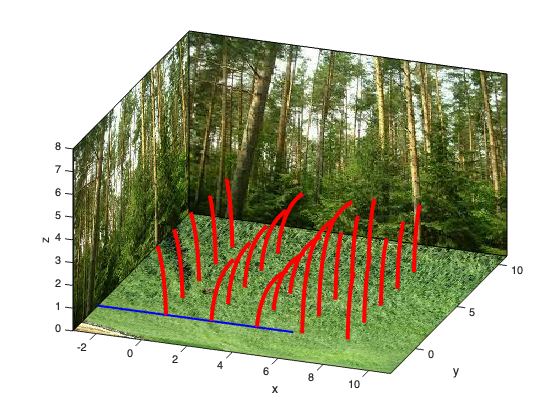

t_vector =    0.100000000000000
   0.100000000000000
   0.100000000000000
   0.100000000000000
   0.100000000000000
   0.100000000000000
   0.100000000000000
   0.100000000000000
   0.100000000000000
   0.100000000000000



% 흔들리는 잔디 25개
% 교재코드 + 배경사진(잔디 풀 나무 등) 추가

num_data=30; % 잔디를 구성하는 점의 개수
x=zeros(3,num_data); % 초기화
x(3,:)=linspace(0,3,num_data); % 잔디 길이(키)를 3으로 만든다



% sin파형으로 잔디가 왔다갔다 하는 것을 구현할 수 있도록
% sin파형을 그리기 위한 주파수 설정
f=0.2; % 주파수
% sin파형에서 degree를 sampling하기 위한 시간 간격이다
% 크면 클수록 sampling 주기가 빨라서 잔디의 움직임이 빠를것이다
% 작으면 작을수록 sampling 주기가 느려서 잔디의 움직임이 느리고 자세할 것이다
dt=0.1; % 시간 간격

% t 0 0.01 0.02 ~ 30
% sin파형에서 sampling을 30까지 할 것이다.
% 이 값이 많으면 많을수록 잔디의 상태를 오래 보여준다
t=0:dt:30; % 시간
num_grass=25;

% 자연스러운 바람에 날리는 잔디를 구현하기 위해
% i가 클수록 (잔디 윗부분일수록)
% and r이 클수록 잔디 회전각도 작음
% and r이 작을수록 잔디 회전각도 큼
% i가 작을수록 (잔디 아랫부분일수록)
% and r이 크던 말던 잔디 회전각도는 크게 영향받지 않는다
r=20; % 각 점의 각도 가중치 변화율 조절

% 자연스럽게 바람에 날린 후 원상태로 복귀하는 것을 구현하기 위해
% 시간에 따른 감소 변화율 조절
% vel_conv값이 커질수록 수렴 속도 느림
% vel_conv값이 작을수록 수렴 속도 빠름
vel_conv=4; % 시간에 따른 감소 변화율 조절

% sin그래프로 t를 샘플링하여
% degree -40~40으로 바꾸어주는 과정
psi2 = (40/180*pi)* (sin(2*pi*f*t));

%그림 띄우기
figure(1); clf;
hold on;

% 25개 잔디와 바람을 그려주기 위해
% 미리 변수에 저장시켜둔다.나중에 변수를 통해 그려줄 것이다
for mm=1:num_grass
    % 25개 각각의 잔디를 그려주는 코드
    ax{mm} = plot3(x(1,:),x(2,:),x(3,:),'-r','LineWidth',4);
    % 25개 각각의 잔디를 어느 좌표상에 위치시킬 것인지 
    % x,y 좌표를 얻는 코드 2줄 (0,0) (2,0).. (6,8) (8,8)
    x_cor(mm)=rem((mm-1),5)*2; % rem: moduler 연산을 해주는 함수. 0 2 4 6 8...0 2 4 6 8 (x좌표)
    y_cor(mm)=fix((mm-1)/5)*2; % fix : 0방향으로 가장 가까운 정수로 변환 00000 22222 .. 8 8 8 8 8 (y좌표)
    ax_wind= plot(0,0,'-b','LineWidth',2); 
end

box on; grid on;
xlim([-3 11]); ylim([-3 11]); zlim([0 8]);
xlabel('x');ylabel('y');zlabel('z');
view(-20,30)

view_count=0;

% 바람 방향 4개
% 바람 방향에 따라 잔디 상태를 업데이트해 줄 것이기 때문에
% 바람 방향 설정에 대한 for문이 먼저 작성되었다
for pp=[0 30 45 80]
    t_vector=dt*ones(num_grass,1)

    wind_x_c=[]; % 바람이 궤적의 x좌표를 누적시키며 저장하기 위한 변수
    wind_y_c=[]; % 바람이 궤적의 y좌표를 누적시키며 저장하기 위한 변수

    wind_direction=pp/180*pi; % 바람 방향
    wind_x=t*5-2; % 바람 x좌표
    wind_y= tan(wind_direction)*wind_x; % 바람 y방향

    % 나중에 바람의 위치에 따라 잔디상태를 구현할 수 있도록하기 위한 변수
    xy_dist_old = ones(num_grass,1)*10; 

% sin파형에서 t를 샘플링하는 횟수
% 30번 샘플링한다
% 그 횟수에 따라 잔디의 상태를 업데이트하는 가장 큰 for문
    for j=1:2:length(t)
        
        % t는 0~30의 시간을 의미하는 변수이다. 시간이 흐름에 따라 바람이 지나가는 좌표값도 증가한다.
        wind_x=t(j)*1-5; 
        % x축 변화량만큼 y축도 비례하여 변화하기 위해 tan()를 사용하였다. (그림참고)
        wind_y=tan(wind_direction)*wind_x; 

        % 간단히 말하면 바람에 대한 for문
        % 바람의 현재위치와 잔디의 위치간의 거리 차에 대한 기울기가 +로 변화하면 잔디가 움직이기 시작
        for mm=1:num_grass
            psi(mm)=psi2(round(t_vector(mm)/dt));
            % 바람의 위치와 mm for문에 해당하는 잔디의 거리를 구한다
            % Euclidean Distance
            xy_dist_new(mm)=sqrt((x_cor(mm)-wind_x)^2+(y_cor(mm)-wind_y)^2); 
            agag(j,mm) = xy_dist_new(mm) - xy_dist_old(mm);
            if xy_dist_new(mm) < xy_dist_old(mm)
                t_vector(mm)=dt;
            end
            t_vector2(mm,j)=t_vector(mm);
        end
        xy_dist_old = xy_dist_new;
        
        % 간단히 말하면 잔디 상태 업데이틑를 위한 for문
        % 25개의 잔디 각각의 밑부분부터 윗부분까지
        % 상태를 업데이트하기 위한 두번째로 큰 for문
        for i=1:size(x,2)
            % 각 점의 회전 각도에 가중치 부여
            weight_a= (exp((i-num_data)/r)); 
            % 바람 방향에 대한 회전 변환 yaw
            Rz1= [cos(wind_direction) -sin(wind_direction) 0;
                 sin(wind_direction) cos(wind_direction) 0;
                 0 0 1];
            
            % 모든 잔디의 해당하는 점의 상태를 업데이트하는 for문
            % 잔디의 밑부분인데 어느 잔디의 밑부분인지
            % 잔디의 윗부분인데 어느 잔디의 윗부분인지
            % 잔디1 ~ 잔디25 각각 동일한 높이의 있는 점에 대한 회전변환
            for mm=1:num_grass

                % 시간에 따라 각도가 감소하는 변환
                weight_b{mm}=exp(-t_vector(mm)/(vel_conv*1)); 

                % pitch
                % 각 점의 회전 각도에 가중치 부여 + 시간에 따라 각도가 감소하는 변환
                Rx{mm}=[cos(weight_b{mm}*weight_a*psi(mm)) 0 sin(weight_b{mm}*weight_a*psi(mm));
                         0                                 1 0;
                       -sin(weight_b{mm}*weight_a*psi(mm)) 0 cos(weight_b{mm}*weight_a*psi(mm))];
                
                % 그림참고
                % 잔디1~25의 각각 제일 아랫부분인 i=1 부분의 상태를 변환한다
                % 잔디1~25의 각각 i=2부분의 상태를 변환한다
                % 잔디1~25의 각각 제일 윗부분인 i=30 부분의 상태를 변환한다
                y{mm}(:,i)=Rz1*Rx{mm}*x(:,i);
            end
        end
        
        % 바람 궤적의 x좌표를 누적시켜준다
        wind_x_c=[wind_x_c wind_x];
        % 바람 궤적의 y좌표를 누적시켜준다
        wind_y_c=[wind_y_c wind_y];

       
        % 잔디상태 업데이트
        for mm=1:num_grass
            % 최신상태의 잔디를 그려준다
            drawnow limitrate
            ax{mm}.XData=y{mm}(1,:) + x_cor(mm);
            ax{mm}.YData=y{mm}(2,:) + y_cor(mm);
            ax{mm}.ZData=y{mm}(3,:);
            % 최신상태의 바람을 그려준다
            ax_wind.XData=wind_x_c;
            ax_wind.YData=wind_y_c;
            refresh % 현재 Figure를 지우고 다시 그립니다.
            t_vector(mm)=t_vector(mm) + dt;
        end
        drawnow limitrate
        % 뷰 업데이트
        view_count=view_count+1;
        view(70*sind(2*pi*0.05*view_count), 10*cosd(2*pi*0.05*view_count)+25)
        
        % xy평면에 이미지 삽입
        xy=imread('x1y1z0.png'); % 이미지파일을 행렬로 저장
        x_vec=[-3 11]; y_vec=[-3 11]; z_vec= [0 8]; % 벡터 x, y, z를 만든다
        imagesc(x_vec,y_vec,xy); % 벡터x, 벡터y에 이미지삽입

        % x=-3, yz 평면에 이미지 삽입
        yz = imread('x0y1z1.png');
        yz_z = [8 8;0 0]; 
        yz_x = [-3 -3; -3 -3];
        yz_y = [-3 11; -3 11];
        % y=11, xz 평면에 이미지 삽입
        xz_x = [-3 11; -3 11];
        xz_y = [11 11;11 11];

        surf(yz_x,yz_y,yz_z,'CData',yz,'FaceColor','texturemap');
        surf(xz_x,xz_y,yz_z, 'CData',yz,'FaceColor','texturemap');
    
    end
end